clc;clear all;close all;
b=0.01;
J=0.5;
A=[0 1;0 -b/J];
B=[0;1/J];
G=[0;1/J];
C=[1 0];
D=0;
%%1er paso LQR
Q=diag([1000 1])

Q =         1000           0
           0           1


R=0.1;
K=lqr(A,B,Q,R)

K =   100.0000   10.4781


Kr=inv(-(C-D*K)*(A-B*K)^-1*B+D)

Kr = 100.0000

% GCL=ss(A-B*K,B*Kr,C-D*K,D*Kr)
% step(GCL)
Qw=0.001;
Vv=0.0001;
L=lqe(A,G,C,Qw,Vv)

L =     3.5366
    6.2538


## Cierras Lazo


x0=[0.3;0.5;0;0]

x0 =     0.3000
    0.5000
         0
         0


[T,X]=ode45(@(t,x_g)sate_I(t,x_g,K,Kr,L,A,B,C,D),[0:0.01:30],x0)

T =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


X =     0.3000    0.5000         0         0
    0.3050    0.4934    0.0106    0.0115
    0.3098    0.4756    0.0210    0.0106
    0.3145    0.4491    0.0312    0.0000
    0.3188    0.4161    0.0410   -0.0180
    0.3228    0.3786    0.0505   -0.0412
    0.3264    0.3381    0.0595   -0.0679
    0.3295    0.2961    0.0680   -0.0967
    0.3323    0.2537    0.0760   -0.1262
    0.3346    0.2118    0.0836   -0.1555


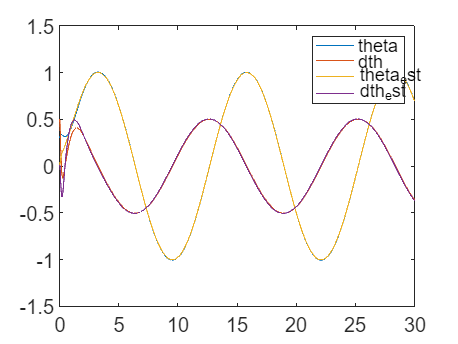

figure
plot(T,X(:,:))
legend('theta','dth','theta_est','dth_est')


figure(2)
plot(T,X(:,1)-X(:,3));hold on
plot(T,X(:,2)-X(:,4))
legend('error est \theta','error est d\theta')

function dx_g=sate_I(t,x_g,K,Kr,L,A,B,C,D)
    %x_g=[x;xi]
    r = sin(0.5*t); % -----> Referencia

    x = x_g(1:2);  % # de estados del sistema
    xhat =x_g(3:4); %#

    u=control(xhat,K,Kr,r); %----> Controlador
    dx=sate(t,x,u);% ----> Planta Original
    y=C*x+D*u;
    dxhat=sate_obs(t,xhat,y,u,L,A,B,C,D); %-----> Planta Observada
    dx_g=[dx;dxhat];
end

%--------------------------------------------
function u=control(xhat,K,Kr,r)
    u=-K*xhat+Kr*r;
end

%--------------------------------------------
% X clon o Observador
function dxhat=sate_obs(t,xhat,y,u,L,A,B,C,D)
    yhat=C*xhat+D*u;
    dxhat=A*xhat+B*u+L*(y-yhat);
end

%-------------------------------------------
% X original
function dx=sate(t,x,u)
    b=0.011;
    J=0.54;
    A=[0 1;0 -b/J];
    B=[0;1/J];
    dx=A*x+B*u;
end